G = [1/50 -1/50 0 1; -1/50 1/50 0 0; 0 0 1e-3 0; 1 0 0 0]

G =     0.0200   -0.0200         0    1.0000
   -0.0200    0.0200         0         0
         0         0    0.0010         0
    1.0000         0         0         0


C = [0 0 0 0; 0 0 0 0; 0 0 1e-4 0; 0 0 0 0]

dT = 0.005; %sec
T = 0:dT:0.5;
V1 = zeros(1, length(T))

V1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


V2 = zeros(1, length(T))

V2 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


V3 = zeros(1, length(T))

V3 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


IE = zeros(1, length(T))

IE =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



%initial conditions
X = zeros(4, length(T));

% initial conditions
V1(1) = 0;
V2(1) = 0;
V3(1) = 0;
X(:, 1) = [V1(1); V2(1); V3(1); IE(1)];

Is = 1e-13;
VT = 0.025;
A = 5; % Amplitude of the sinusoidal voltage source
omega = 2 * pi * 60; % Angular frequency (60 Hz)

[V1, V2, V3, IE] = transient_response(G, C, dT, T, A, omega, Is, VT);


plot

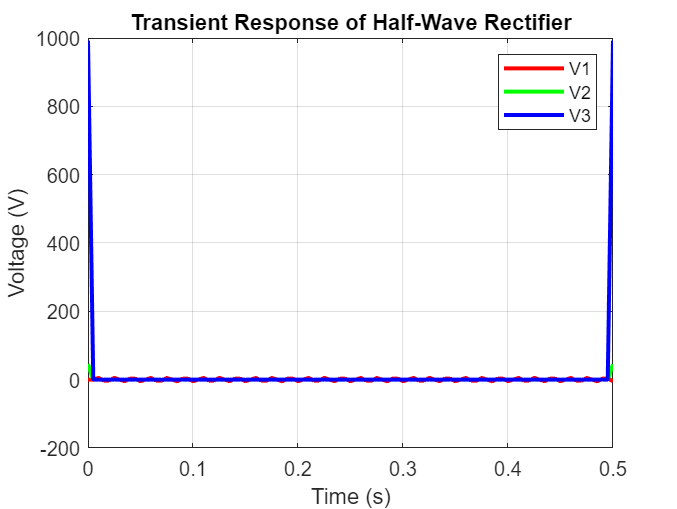

figure;
plot(T, V1, 'r', 'LineWidth', 2);
hold on;
plot(T, V2, 'g', 'LineWidth', 2);
plot(T, V3, 'b', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Voltage (V)');
title('Transient Response of Half-Wave Rectifier');
legend('V1', 'V2', 'V3');
grid on;

appendix

function [V1, V2, V3, IE] = transient_response(G, C, dT, T, A, omega, Is, VT)
    % Initialize the output arrays
    V1 = zeros(1, length(T));
    V2 = zeros(1, length(T));
    V3 = zeros(1, length(T));
    IE = zeros(1, length(T));
    X = zeros(4, length(T));

    % Loop through each time step and calculate the corresponding values
    for i = 1:length(T) - 1
        % Solve the system of equations
        x0 = X(:, i); % initial guess
        options = optimoptions('fsolve', 'Display', 'none'); % suppress the output of fsolve
        X_next = fsolve(@(x) eqns(x, G, C, dT, T(i), A, omega, Is, VT, X(:, i)), x0, options);

        % Update the next state
        X(:, i+1) = X_next;
        V1(i+1) = X_next(1);
        V2(i+1) = X_next(2);
        V3(i+1) = X_next(3);
        IE(i+1) = X_next(4);
    end

    % Define the function D(X(t))
    function DX = d_x(x, Is, VT)
        V2 = x(2);
        V3 = x(3);
        DX = [0; Is*exp((V2-V3)/VT)-1; -Is*exp((V2-V3)/VT)-1; 0];
    end

    % Define the function B(t)
    function Bt = b_t(t, A, omega)
        Bt = [0; 0; 0; A*sin(omega*t)];
    end

    % Define the system of equations to be solved
    function F = eqns(x, G, C, dT, t, A, omega, Is, VT, current)
        Gx = G * x;
        dXdt = (x - current) / dT;
        Cdxdt = C * dXdt;
        DX = d_x(x, Is, VT);
        Bt = b_t(t, A, omega);
        F = Gx + Cdxdt + DX - Bt - [0; 0; 0; 0];
    end
end


This approach is efficient in terms of CPU cost and accuracy, as it uses a numerical method (`fsolve`) to solve the nonlinear system of equations for each time step, ensuring a balance between accuracy and computational efficiency. The algorithm can be easily modified to analyze other circuits by changing the input matrices G, C, and the functions B(t) and D(X(t)) accordingly.

It can also handle circuits of different sizes, and MATLAB's built-in functions are designed to handle large matrices efficiently. However, we believe that as the circuit size increases, the computational complexity and time required will also increase. To improve efficiency for large circuits, we would have to explore other numerical methods, such as the Newton-Raphson method, to solve the nonlinear systems of equations or parallelize the code using MATLAB's parallel computing features.